# Project 3

## Objective

Designing a control system for given plant having $PM>40$ and setteling time for 5% settling less than 1 sec. Observing effect of time delay on the system to determine sensor latency whsettlingich can be tolerated for before the system goes unstable.

## Introduction

Dynamic System transfer function is as below-


$$\frac{Y}{U} = \frac{50(s+4)}{s(s+6)(s^2+4s+25)}$$


Design Requirements-

Phase margin for the final system greater than 40, velocity error ($K_v$ ) for the system is greater than $\frac{20}{3}$ and step response 5% settling time is less than 1sec, with actuator force not exceeding +15$N$. 

% Cleanup
clearvars
close ('all')

% Defining plant transfer function in MATLAB
g1 = 50*tf([1 4],conv([1 6 0],[1 4 25]));            % Initial System Transfer function

## Control System Design

For velocity error constant $K_v$ to be greater than $\frac{20}{3}$.

Let us assume system have loop gain as $K_c$,hence the loop transfer function will become-


$$G_l(s) =  \frac{50K_c(s+4)}{s(s+6)(s^2+4s+25)}$$


we have,


$$K_v = \lim_{s\rightarrow 0} s*G_l(s)$$


By substituting above values, we get,


$$K_v = \lim_{s\rightarrow 0}s*\frac{50K_c(s+4)}{s(s+6)(s^2+4s+25)}$$



$$K_v = \lim_{s\rightarrow 0}\frac{50K_c(s+4)}{(s+6)(s^2+4s+25)}$$


Hence, $K_v = \frac{50*4*K_c}{6*25}$


$$K_v = \frac{4}{3}K_c$$


We have, $K_v>\frac{20}{3}$

hence, $\frac{4}{3}K_c>\frac{20}{3}$

We get, condition for loop gain as below,


$$K_c>5$$


Steady state error for the system for ramp input can be obtained as below-

we have,$e_{ss} = \frac{A}{K_v}$

If $A = 1$we get, $e_{ss} = \frac{1}{K_v$

But, we have condition as, $K_v>\frac{20}{3}$

hence, we get condition for steady state error as-


$$e_{ss} < \frac{3}{20}$$


For initial system, phase margin observed to be 82 degrees, against the required of 40deg. 

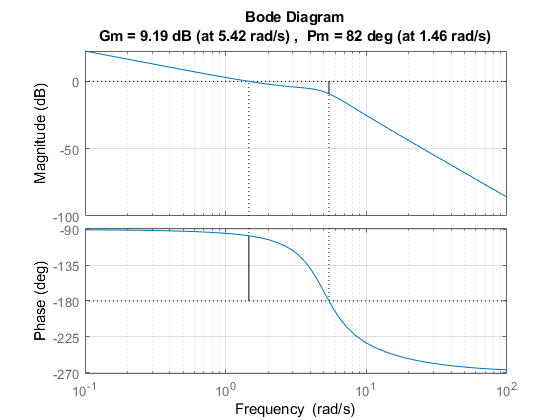

% Phase margin check for initial
[mg1,ph1] = margin(g1);
margin(g1);grid on;hold off                 % vefifying system for available phase margin and stability range

Range for stability of K from bode plot of the system can be observed as below-

% Range stability of K with initial system Bode plot
k = 10^(9.19/20);

For stability we get range as-

$1<k<2.8810$, where as to achieve steady state error requirement we require,$k>5$

With gain for system greater than 5, initially system was designed with gain of 5.2, but for the requirement of actuator force less than +15$Nm$, filters were required to be added to the input command in simulations, hence response by the system for settling time was delayed from the designed for 1 sec at 5% settling time, hence settling time with system design is targeted for 0.6 sec against required of 1 sec and gain value for lead compensator design to include in loop transfer function used is 10, which will satisfy the requirement for steady state error.

% Phase margin for the system with loop gain of 10
kc = 10;                       % DC gain required for the system to aceive k_v  requirement
[mgkc, phkc] = margin(kc*g1);

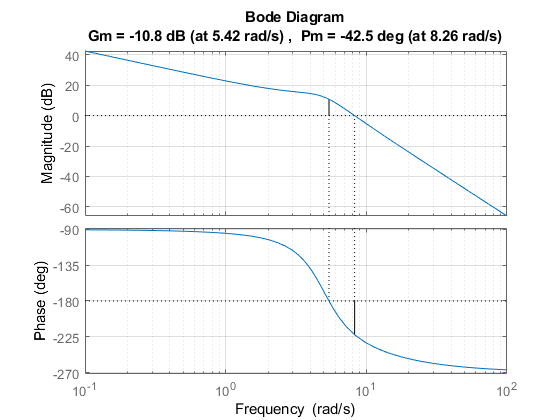

margin(kc*g1);grid on;hold off

Phase margin of the system is -42.5 deg against required of 40deg.

Hence, lead compensator will be required to be added in system which will provide phase lead of (40+42.5 = 82.5) 83 deg, to obtain the required response from the system.

As phase required is greater than 50degree, initial decision was to use two lead compensators providing phase lead of 49 and 34 respectively.

Below were the formulas used for the design of the lead compensator


$$\alpha = \frac{1-sin\phi_m}{1+sin\phi_m$$


where, $\alpha $ is one of the design parameters lead compensator and $\phi_m$ is the phase to be added


$$|G_m(\omega_m)| = 10log_{10}\alpha$$


where, $\omega_m$ is the frequency at which the gain calculated in dB from above formula is observed, and it is the frequency which is used for adding the lead compensator.


$$T = \frac{1}{\omega_m\sqrt{\alpha$$


where, $T$ is the design parameter for lead compensator.

From above formulas, we get lead compensator as-


$$D(s) = \frac{Ts+1}{\alpha Ts+1$$


% 1st Lead Phase compenstor design
phi1 = 49;                      % Phase required with first lead compenstor
phi_m1 = phi1;                   % Phase taken for design
alpha1 = (1-sind(phi_m1))/(1+sind(phi_m1));  % parameter for design
dB1 = 10*log10(alpha1);          % gain value for frequency at which compensator to be added
% Obtaining frequency corresponding to gain
% wm = 1:0.01:20;              % defined range of frequency
% for ii = 1:length(wm)
%     dbc = 20*log10(abs(evalfr(kc*g1,wm(ii)*1i)));
%     if dB1>=dbc
%         rwm1 = wm(ii)              % frequency at which compensator to be added
%         break
%     end
% end
rwm1 = 11.26;                       % frequency at which compensator to be added

From the calculations frequency for adding phase lead compensator observed to be 11.26$rad/s$

% Phase added with design
phase_value = angle(evalfr(kc*g1,rwm1*1i))*180/pi;
if phase_value >0 || phase_value == 180
    new_PM = -(180 - phase_value);
else
    new_PM = 180 + phase_value;
end
phase_lost = phkc - new_PM;                     % Extra Phase loss from original phase loss
phase_obtained_designe1 = phi1 - phase_lost;    % phase obtained from the design
final_estimated_phase = phkc + phase_obtained_designe1; % Phase eastimation from calculations done
T1 = 1/(rwm1*sqrt(alpha1));      % paramter for lead compensator
% First Lead phase compensator
D1 = tf([T1 1],[alpha1*T1 1]);   % 1st lead compensator
[mg3,ph3] = margin(D1*kc*g1);   % Phase received form the first lead compensator

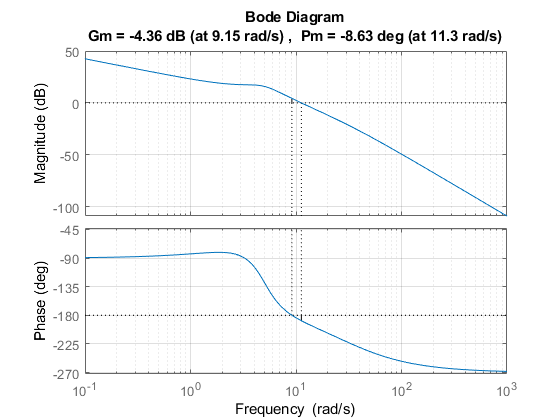

margin(D1*kc*g1);grid on
hold off

First lead compensator for designed for phase lead of 49, observed to be providing the phase lead of 33.82 deg against targeted 49deg, final PM of the system with one lead compensator designed observed to be -8.62deg. Hence for design requirement, additional phase of 48deg is required, hence second lead compensator designed to provide phase lead of 49 deg. 

First compensator obtained from design is as below-


$$D_1(s) = \frac{0.2375s+1}{0.0332s+1}$$


% 2nd Lead Phase compenstor design
phi2 = 49;                % Required phase from the second compensator
phi_m2 = phi2;            % Phase for designing the compensator
alpha2 = (1-sind(phi_m2))/(1+sind(phi_m2));
dB2 = 10*log10(alpha2);
% Obtaining frequency corresponding to gain
% wm = 10:0.01:20;
% for ii = 1:length(wm)
%     dbc = 20*log10(abs(evalfr(kc*D1*g1,wm(ii)*1i)));
%     if dB2>=dbc
%         rwm2 = wm(ii)
%         break
%     end
% end
rwm2 = 17.1;            % Frequency at which second compensator is added

Frequency for adding second lead compensator observed to be 17.1$rad/s$

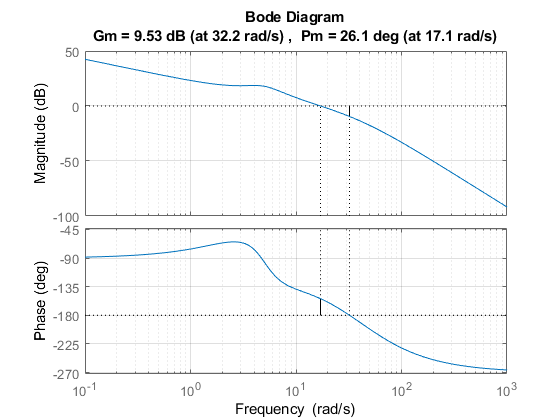

% Phase added with design
% phase_value = angle(evalfr(kc*D1*g1,rwm2*1i))*180/pi;
% if phase_value >0 || phase_value == 180
%     new_PM2 = -(180 - phase_value);
% else
%     new_PM2 = 180 + phase_value;
% end
% phase_lost2 = ph3 - new_PM2;                 % Extra Phase loss from original phase loss
% phase_obtained_designe2 = phi_m2 - phase_lost2;    % phase obtained from the design
% final_estimated_phase = phkc + phase_obtained_designe1 + phase_obtained_designe2;
T2 = 1/(rwm2*sqrt(alpha2));
% Lead phase compensator
D2 = tf([T2 1],[alpha2*T2 1]);
%% raph for the system
[mg4,ph4] = margin(D2*D1*kc*g1);
margin(D1*D2*kc*g1);grid on;hold off

Second lead compensator for designed for phase lead of 49, observed to be providing the phase lead of 26.08 deg against targeted 49deg, final PM of the system with two lead compensators designed observed to be 26.123deg. Hence to satisfy design requirement, additional phase of 13.88deg is required, by checking phase graph the system with two compensator, phase lead compensator designed with phase lead of 23.80deg against the required 13.88deg. 

Second lead compensator designed is as below-


$$D_2(s) = \frac{0.1564s+1}{0.02186s+1}$$


% 3rd Lead Phase compenstor design
phi3 = 41 - ph4;                % Required phase from the second compensator
phi_m3 = phi3*1.6;              % Phase for designing the compensator
alpha3 = (1-sind(phi_m3))/(1+sind(phi_m3));
dB3 = 10*log10(alpha3);
%% Obtaining frequency corresponding to gain
% wm = 20:0.01:25;
% for ii = 1:length(wm)
%     dbc = 20*log10(abs(evalfr(kc*D1*D2*g1,wm(ii)*1i)));
%     if dB3>=dbc
%         rwm3 = wm(ii)
%         break
%     end
% end
rwm3 = 22.2;            % frequency at which third compensator is added

Frequency for adding third compensator observed to be 22.2$rad/s$.

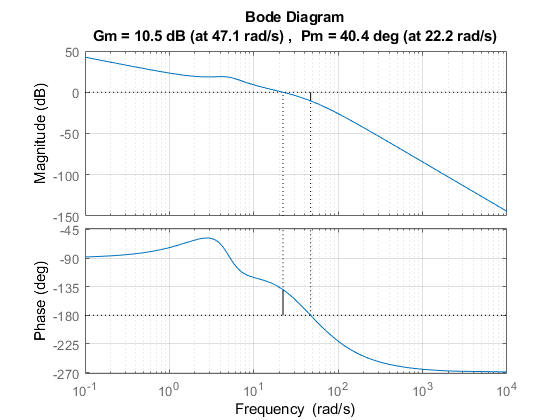

% Phase added with design
% phase_value = angle(evalfr(kc*D1*D2*g1,rwm3*1i))*180/pi;
% if phase_value >0 || phase_value == 180
%     new_PM3 = -(180 - phase_value);
% else
%     new_PM3 = 180 + phase_value;
% end
% phase_lost3 = ph4 - new_PM3;                        % Extra Phase loss from original phase loss
% phase_obtained_designe3 = phi_m3 - phase_lost3;     % phase obtained from the design
% final_estimated_phase = phkc + phase_obtained_designe1 + phase_obtained_designe2 + phase_obtained_designe3;
T3 = 1/(rwm3*sqrt(alpha3));
% Lead phase compensator
D3 = tf([T3 1],[alpha3*T3 1]);
% phase margin for the designed system
[mgf,phf] = margin(kc*D1*D2*D3*g1);
margin(kc*D1*D2*D3*g1);grid on;hold off

With the third lead compensator in system, total system phase margin observed to be 40.3852deg against required 40deg. Third lead compensator provided the value of 14.2463deg against targeted 23.80 deg.

Third lead compensator designed is as below-


$$D_3(s) = \frac{0.0691s+1}{0.02936s+1}$$


With three designed lead compensators and gain of 10, Block diagram of the system can be represented as below-

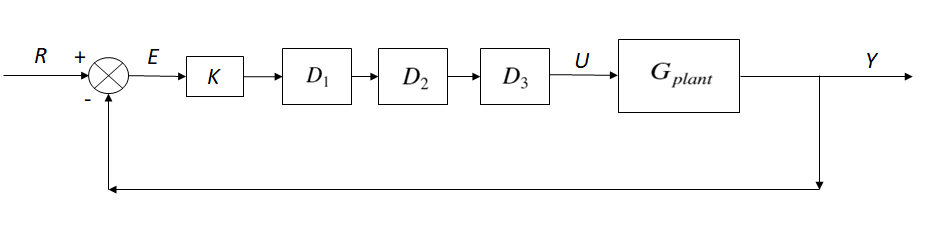

Where,

$K_c = 10$,$D_1(s) = \frac{0.2375s+1}{0.0332s+1}$,$D_2(s) = \frac{0.1564s+1}{0.02186s+1}$,$D_3(s) = \frac{0.0691s+1}{0.02936s+1}$

ST = 0.05;
gcl = feedback(kc*D1*D2*D3*g1,1);
S = stepinfo(gcl,'SettlingTimeThreashhold',ST);
S.SettlingTime;

For designed system, 5% settling time observed to be 0.56sec against targeted 0.6sec. Below graph provide response of the system observed without filters.

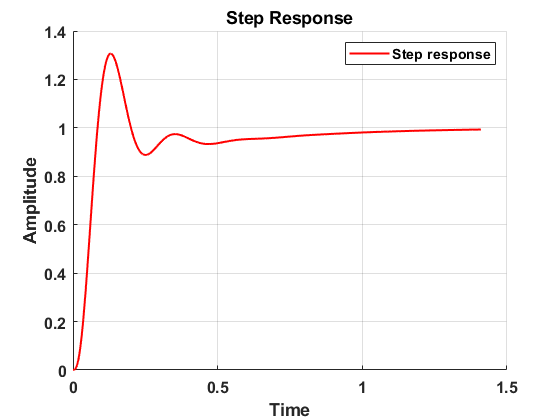

%% for plotting step response of the system
[res,time] = step(gcl);
% plotting step response
LW = 1.5;                                     % linewidth for lines
FS = 12;                                      % Font width
id1 = 10;                                      % for step response
h(id1).fig =figure(id1);                      % makeing figure
h(id1).axs =axes;                             % Make axies
h(id1).ln(1)=line(time,res,'Color','r');      % stable system
h(id1).xlb = xlabel('Time');                  % Xlabel for plot1
h(id1).ylb = ylabel('Amplitude');             % Ylabel for plot1
h(id1).leg = legend('Step response');         % legends
h(id1).tit = title('Step Response');          % title for plot
%Plot formatting
for i=1:length(h(id1).ln)                     % Setting linewidth for first plot
    h(id1).ln(i).LineWidth = LW;
end
h(id1).axs.FontSize   = FS;                   % axis font size for first plot
h(id1).axs.FontWeight = 'Bold';               % Set axis type for first plot
grid;

%% System response with input command filters
tau = 0.15;                         % filter time constant
tf_filt = tf([1 0],conv([0.15 1],[1 0]));
S2 = stepinfo(tf_filt*tf_filt*gcl,'SettlingTimeThreashhold',ST);
S2.SettlingTime;

By adding filters in the system final settling time for the system observed to be 0.9765sec for 5% settling against required 1sec. Below is the step response from the system with filters used-

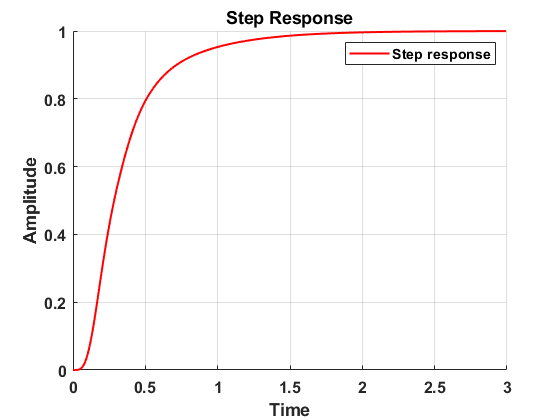

%% for plotting step response of the system
[res1,time1] = step(tf_filt*tf_filt*gcl);
% plotting step response with filter
id2 = id1+1;                                  % for step response
h(id2).fig =figure(id2);                      % makeing figure
h(id2).axs =axes;                             % Make axies
h(id2).ln(1)=line(time1,res1,'Color','r');    % stable system
h(id2).xlb = xlabel('Time');                  % Xlabel for plot1
h(id2).ylb = ylabel('Amplitude');             % Ylabel for plot1
h(id2).leg = legend('Step response');         % legends
h(id2).tit = title('Step Response');          % title for plot
%Plot formatting
for i=1:length(h(id2).ln)                     % Setting linewidth for first plot
    h(id2).ln(i).LineWidth = LW;
end
h(id2).axs.FontSize   = FS;                   % axis font size for first plot
h(id2).axs.FontWeight = 'Bold';               % Set axis type for first plot
grid;

Closed loop system bode plot for the final design with two phase lead compensators is as shown below-

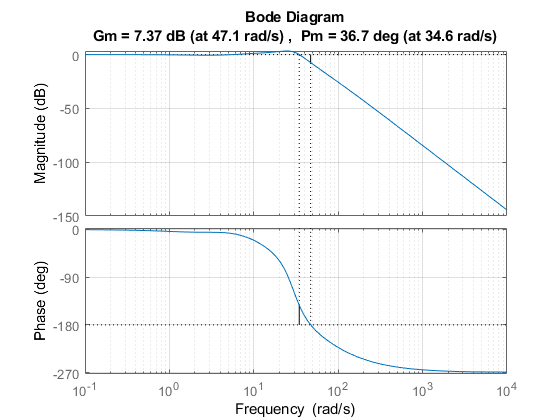

% Bandwidth for the designed system
margin(gcl);grid on

For the closed loop system, bandwidth observed to be 39.5rad/s.

## Design Verification with Root Locus

For only plant in loop, characteristic equation for the system can be represented as-


$$1+K_c*G_{plant} = 0$$


Hence loop transfer function for root locus will be-


$$G_l = G_{plant} = \frac{50(s+4)}{s(s+6)(s^2+4s+25)}$$


For initial system root locus observed to be as below-

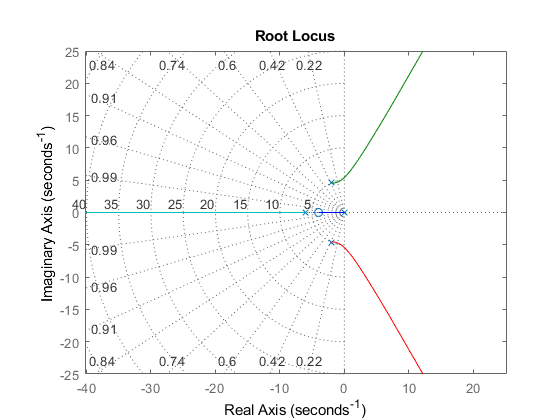

%% roots for the k=10 for the initial system
% [ri,ki] = rlocus(g1);
% for ii = 1:length(ki)
%     if ki(ii) >= 10
%         rti = ri(:,ii)
%         break
%     end
% end
% Root locus for the initial system
rlocus(g1)
axis equal
sgrid

As from earlier design for $K_v>\frac{20}{3}$ gain value for the system observed to be required as $K>5$. At Around $K>2.75$ roots locus enters into the RHP making system unstable. For selected value of gain, without compensator roots for the system observed to be -3.6164 + 0.0000i, 1.7208 + 7.5345i, -9.8253 + 0.0000i. Initially for the required gain system had two poles in RHP and system goes unstable for the high gains as seen from the bode plot earlier.

Below is the loop transfer function for the designed system, which can be represented as-

Characteristic equation for the system will be-


$$1+K_c*D_1*D_2*D_3*G_{plant} = 0$$


Hence loop transfer function for the system will be-

$G_l(s) = D_1*D_2*D_3*G_{plant}$ and we have taken $K_c = 10$ for the final system.

Root locus for the designed system is as below-

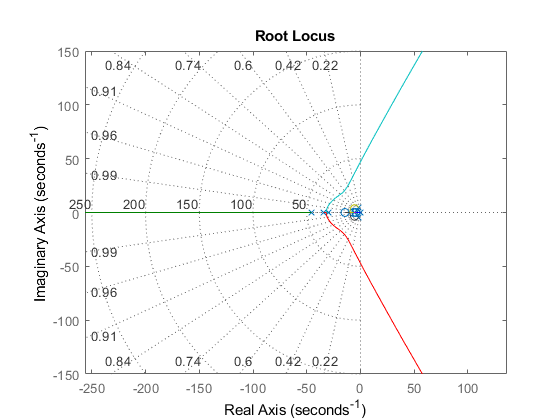

% Root locus for the designed system
rlocus(D1*D2*D3*g1)
axis equal
sgrid;hold off

%% roots for the k=10 for the initial system
% [rf,kf] = rlocus(D1*D2*D3*g1);
% for ii = 1:length(kf)
%     if kf(ii) >= 10
%         rtf = rf(:,ii)
%         break
%     end
% end

With the designed system, system observed to have 7 poles, and all the roots for the $K_c = 10$ observed to be in LHP -2.5832, -74.2808, -9.2523 +29.3276i, -5.8286, -9.3559 + 3.4430i against the earlier, with two poles in RHP. Designed system is stable.  At $K_c = 10$ on root locus plot we get, $\zeta = 0.345 $ and $\omega_n = 29.5rad/s$. By using the time domain analysis tool, approximate settling time for the system can be observed to be as below-


$$t_s = \frac{4.6}{\zeta \omega_n$$


After substituting values obtained from the root locus for the designed system at $K_c =10$ we get settling time to be 0.452sec against targeted 0.6sec for the system.

% % settling time from time domain analysis
% zeta = 0.345;       % damping ratio observed
% wn = 29.5;          % natural frequency observed
% ts = 4.6/(zeta*wn);

## Design Verification with Nyquist

With initial system, characteristic equation for the system can be represented as-


$$1+K_c*G_{plant} = 0$$


Hence loop transfer function for Nyquist plot will be-


$$G_l = G_{plant} = \frac{50(s+4)}{s(s+6)(s^2+4s+25)}$$


From the MATLAB command we get Nyquist plot as below-

% MATLAB code for Nyquist plot from matlab
% nyquist(g1);axis equal;grid on

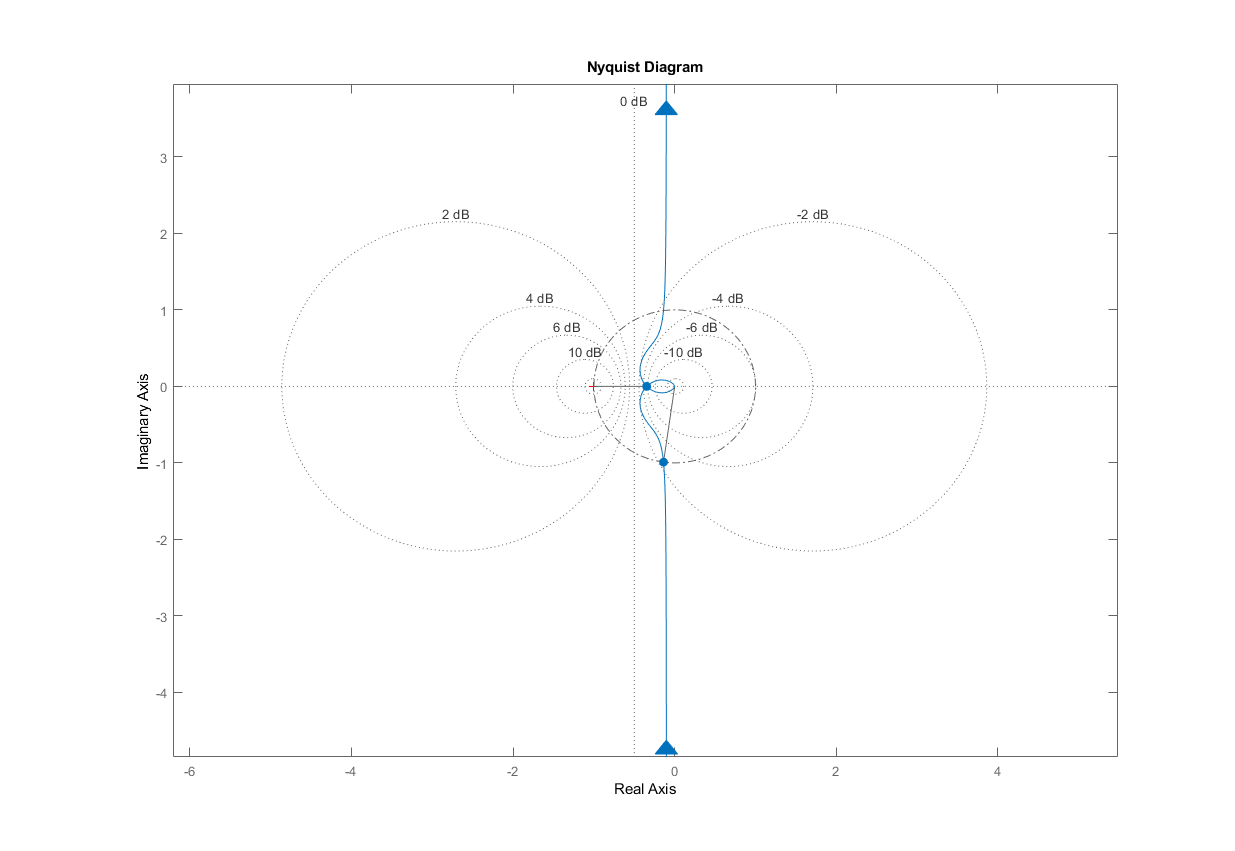

Same prepared with below MATLAB code considering maximum frequency as 50rad/sec.

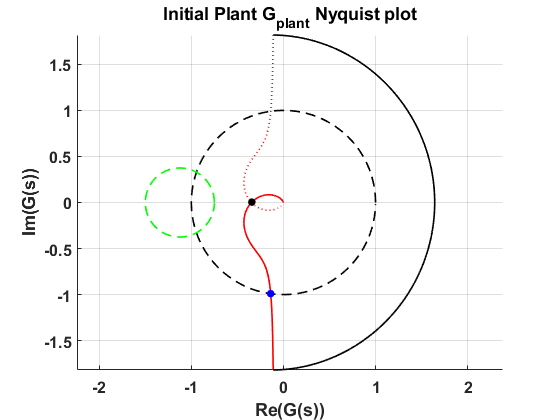

%% Nyquist plot for the initial system
g = g1;
r = 0.75;                        % Define radius for the pole at the origin
wMax = 50;                      % largest w value
%% s = rj -> wMax j
s1 = (r:.1:wMax)' * (1i);       % getting s value on imaginary axis to substitute in transfer function for obtaining nyquit plot points
nyq1 = zeros(size(s1));
for k = 1:length(s1)
    nyq1(k) = evalfr(g,s1(k));  % Getting nyquist plot points
end

%% s = re^(j*phi), phi = -90 -> 90
phi = (-90:1:90)';              % getting phi for values at circle considered in nyquist plot 
s2 = ( r*cosd(phi) + (1i)*r*sind(phi) ); % value of comples number to substitute in transfer function for getting nyquist plot values
nyq2 = zeros(size(s2));
for k = 1:length(s2)
    nyq2(k) = evalfr(g,s2(k));  % evaluation nyquist plot values
end

%% s = -rj -> -wMax j
s1a = (-r:-.01:-wMax)' * (1i);  % for -ve side of the imaginary axis
nyq1a = zeros(size(s1a));
for k = 1:length(s1a)
  nyq1a(k) = evalfr(g,s1a(k));  % evaluating points for the nyquist plot
end

%% Unit Circle- for phase margin
tht = 0:1:359;
x = cosd(tht);          % x points on the unit circle
y = sind(tht);          % y points on the unit circle

%% An M circle- for resonant frequncy, bandwidth
M = -3;
tht=0:1:359;
r = abs(M./(M.^2-1));   % radius for m circle
xc = M.^2./(1-M.^2);    % x related point on the M circle
for k=1:length(xc)
  mc(k).c = xc(k) + r(k)*(cosd(tht)+sind(tht)*(1i));    % points for the M circle with respect to M value
end
%% PM- with help from unit circle cross point in the nyquist plot
    idL = find(abs(nyq1)<1,1);      % find the indices for number from which nyquist data less than magnitude of 1 for complex number
    idH = idL-1;                    % subtract 1 from the total number values
    ww = [s1(idL) s1(idH)];         % new vector with two points having magnitude on either side of magnitude 1
                                    % abs(s1(idL))<1<abs(s1(idH))
    mm = abs([nyq1(idL) nyq1(idH)]);% new vector with values of those magnitude
    wGC = interp1(mm,ww,1);         % interpolation command to otain exact s value which lies on unity circle
    pPT = evalfr(g,wGC);            % determining the complex number lying on unity circle and on nyquist plot

zAng = angle(pPT)*180/pi - 180; % phase margin for the point obtained
% to represent the phase margin with -180 to 180 window as displayed with margin command 
if zAng < -180
  pM = (zAng+360);
else
  pM = (zAng);
end
%% GM old
idL = find(imag(nyq1)>0,1); % finding no of values in nyquist which are on +ve side of imaginary axis(or I and II quadrant) 
wPC = s1(idL);              % finding first number at which crossover happened
gM = -20*log10(abs(nyq1(idL))); % calulating dB value for the cross over point
gPT = nyq1(idL);   

%% Plotting of figure
id3=id1+2;
LW = 1.2;
h(id3).fig = figure(id3);
h(id3).axs = axes;
h(id3).ln(1) = line(real(nyq1),imag(nyq1),'Color','r','LineStyle','-','Linewidth',LW);  % plot corresponding to points on imaginary axis after small circle for the pole at origin
h(id3).ln(3) = line(real(nyq2),imag(nyq2),'Color','k','LineStyle','-','Linewidth',LW);  % plot corresponding to small circle around point at origin
h(id3).ln(4) = line(real(nyq1a),imag(nyq1a),'Color','r','LineStyle',':','Linewidth',LW);% plot corresponding to - ve side points on the imaginary axis    
h(id3).ln(5) = line(x,y,'Color','k','LineStyle','--','Linewidth',LW);                   % unit circle plot
% blue dot for phase margin
h(id3).ln(6) = line(real(pPT),imag(pPT),'Marker','o','MarkerSize',5,'LineStyle','none','Color','b','MarkerFaceColor','b');
% blue dot for gain margin
h(id3).ln(7) = line(real(gPT),imag(gPT),'Marker','o','MarkerSize',5,'LineStyle','none','Color','k','MarkerFaceColor','k');
% plot for M circles
for k=1:length(mc)
    h(id3).ln(7+k) = line(real(mc(k).c),imag(mc(k).c),'Color','g','LineStyle','--','Linewidth',LW);
end

axis equal 
h(id3).tit = title('Initial Plant G_{plant} Nyquist plot');
h(id3).xlb = xlabel('Re(G(s))');
h(id3).ylb = ylabel('Im(G(s))');
% h(id3).leg = legend('Points for +ve Imag axis s-value','Points corre. to max frequency','Points for -ve Imag axis s-value','Unit Circle','PM','GM','3dB circle');
h(id3).axs.FontSize   = FS;                   % axis font size for first plot
h(id3).axs.FontWeight = 'Bold';               % Set axis type for first plot
grid on

From the initial Nyquist plot available for the system, it can be observed that gain margin for the system is 9.4dB and phase margin for the system is 82.0373deg. which provide range for $K_c $ as $0<K_c<2.951$

For required stead state error, we have $K_c>5$. With selected $K_c =10$ Nyquist plot for the system observed to be as below-

From the MATLAB command we get Nyquist plot as below-

 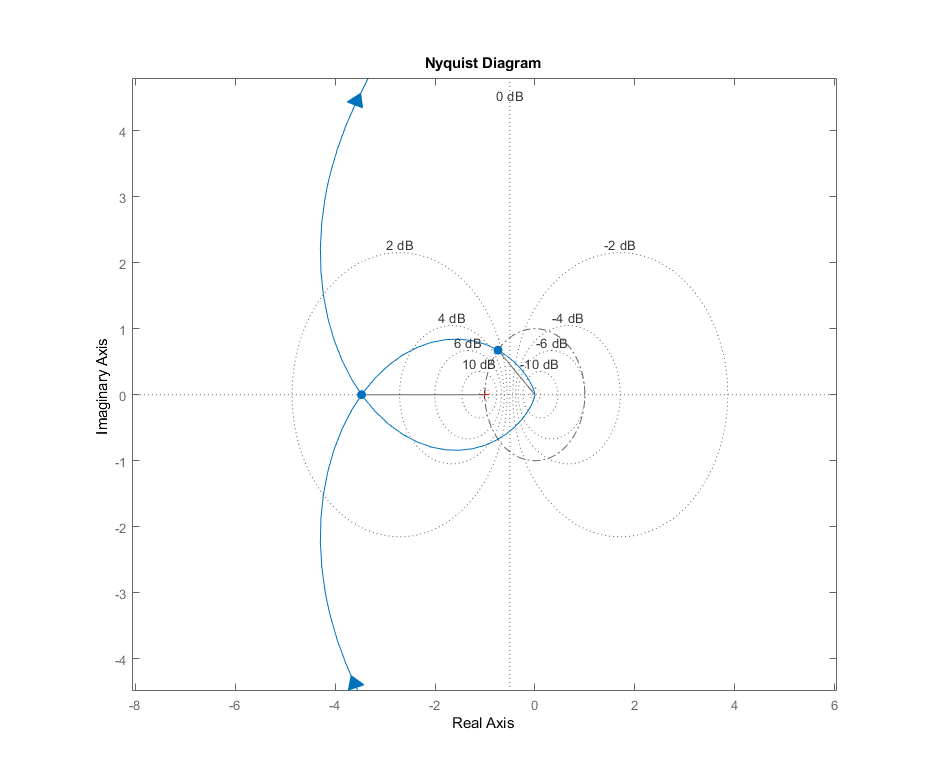

by considering maximum frequency as 50$rad/sec$ we get, Nyquist plot as below

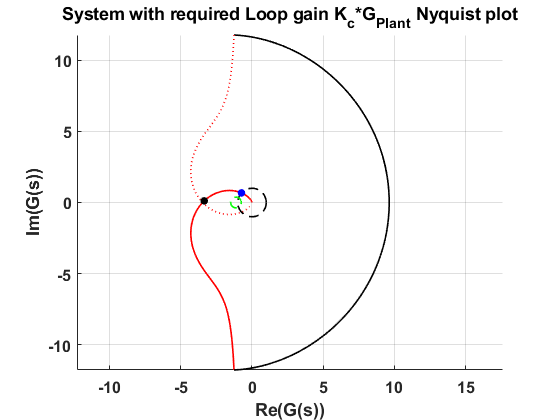

%% Nyquist plot for the initial system
g = kc*g1;
r = 1.2;                        % Define radius for the pole at the origin
wMax = 50;                      % largest w value
%% s = rj -> wMax j
s1 = (r:.1:wMax)' * (1i);       % getting s value on imaginary axis to substitute in transfer function for obtaining nyquit plot points
nyq1 = zeros(size(s1));
for k = 1:length(s1)
    nyq1(k) = evalfr(g,s1(k));  % Getting nyquist plot points
end

%% s = re^(j*phi), phi = -90 -> 90
phi = (-90:1:90)';              % getting phi for values at circle considered in nyquist plot 
s2 = ( r*cosd(phi) + (1i)*r*sind(phi) ); % value of comples number to substitute in transfer function for getting nyquist plot values
nyq2 = zeros(size(s2));
for k = 1:length(s2)
    nyq2(k) = evalfr(g,s2(k));  % evaluation nyquist plot values
end

%% s = -rj -> -wMax j
s1a = (-r:-.01:-wMax)' * (1i);  % for -ve side of the imaginary axis
nyq1a = zeros(size(s1a));       
for k = 1:length(s1a)
  nyq1a(k) = evalfr(g,s1a(k));  % evaluating points for the nyquist plot
end

%% Unit Circle- for phase margin
tht = 0:1:359;
x = cosd(tht);          % x points on the unit circle
y = sind(tht);          % y points on the unit circle

%% An M circle- for resonant frequncy, bandwidth
M = -3;
tht=0:1:359;
r = abs(M./(M.^2-1));   % radius for m circle
xc = M.^2./(1-M.^2);    % x related point on the M circle
for k=1:length(xc)
  mc(k).c = xc(k) + r(k)*(cosd(tht)+sind(tht)*(1i));    % points for the M circle with respect to M value
end
%% PM- with help from unit circle cross point in the nyquist plot
    idL = find(abs(nyq1)<1,1);      % find the indices for number from which nyquist data less than magnitude of 1 for complex number
    idH = idL-1;                    % subtract 1 from the total number values
    ww = [s1(idL) s1(idH)];         % new vector with two points having magnitude on either side of magnitude 1
                                    % abs(s1(idL))<1<abs(s1(idH))
    mm = abs([nyq1(idL) nyq1(idH)]);% new vector with values of those magnitude
    wGC = interp1(mm,ww,1);         % interpolation command to otain exact s value which lies on unity circle
    pPT = evalfr(g,wGC);            % determining the complex number lying on unity circle and on nyquist plot

zAng = angle(pPT)*180/pi - 180; % phase margin for the point obtained
% to represent the phase margin with -180 to 180 window as displayed with margin command 
if zAng < -180
  pM = (zAng+360);
else
  pM = (zAng);
end
%% GM old
idL = find(imag(nyq1)>0,1); % finding no of values in nyquist which are on +ve side of imaginary axis(or I and II quadrant) 
wPC = s1(idL);              % finding first number at which crossover happened
gM = -20*log10(abs(nyq1(idL))); % calulating dB value for the cross over point
gPT = nyq1(idL);   

%% Plotting of figure
id4=id1+3;
LW = 1.2;
h(id4).fig = figure(id4);
h(id4).axs = axes;
h(id4).ln(1) = line(real(nyq1),imag(nyq1),'Color','r','LineStyle','-','Linewidth',LW);  % plot corresponding to points on imaginary axis after small circle for the pole at origin
h(id4).ln(3) = line(real(nyq2),imag(nyq2),'Color','k','LineStyle','-','Linewidth',LW);  % plot corresponding to small circle around point at origin
h(id4).ln(4) = line(real(nyq1a),imag(nyq1a),'Color','r','LineStyle',':','Linewidth',LW);% plot corresponding to - ve side points on the imaginary axis    
h(id4).ln(5) = line(x,y,'Color','k','LineStyle','--','Linewidth',LW);                   % unit circle plot
% blue dot for phase margin
h(id4).ln(6) = line(real(pPT),imag(pPT),'Marker','o','MarkerSize',5,'LineStyle','none','Color','b','MarkerFaceColor','b');
% blue dot for gain margin
h(id4).ln(7) = line(real(gPT),imag(gPT),'Marker','o','MarkerSize',5,'LineStyle','none','Color','k','MarkerFaceColor','k');
% plot for M circles
for k=1:length(mc)
    h(id4).ln(7+k) = line(real(mc(k).c),imag(mc(k).c),'Color','g','LineStyle','--','Linewidth',LW);
end

axis equal 
h(id4).tit = title('System with required Loop gain K_{c}*G_{Plant} Nyquist plot');
h(id4).xlb = xlabel('Re(G(s))');
h(id4).ylb = ylabel('Im(G(s))');
% h(id4).leg = legend('Points for +ve Imag axis s-value','Points corre. to max frequency','Points for -ve Imag axis s-value','Unit Circle','PM','GM','3dB circle');
h(id4).axs.FontSize   = FS;                   % axis font size for first plot
h(id4).axs.FontWeight = 'Bold';               % Set axis type for first plot
grid on

By considering the $K_c$ required for the system, phase margin of the system observed to be -42.46deg, as observed with the bode plot and system observed to be unstable.

As mentioned earlier loop transfer function for the designed system is as below-


$$G_l(s) = K_c*D_1*D_2*D_3*G_{plant}$$


From the MATLAB command we get Nyquist plot as below-

% Nyquist plot with MATLAB command
% nyquist(kc*D1*D2*D3*g1);axis equal;grid on

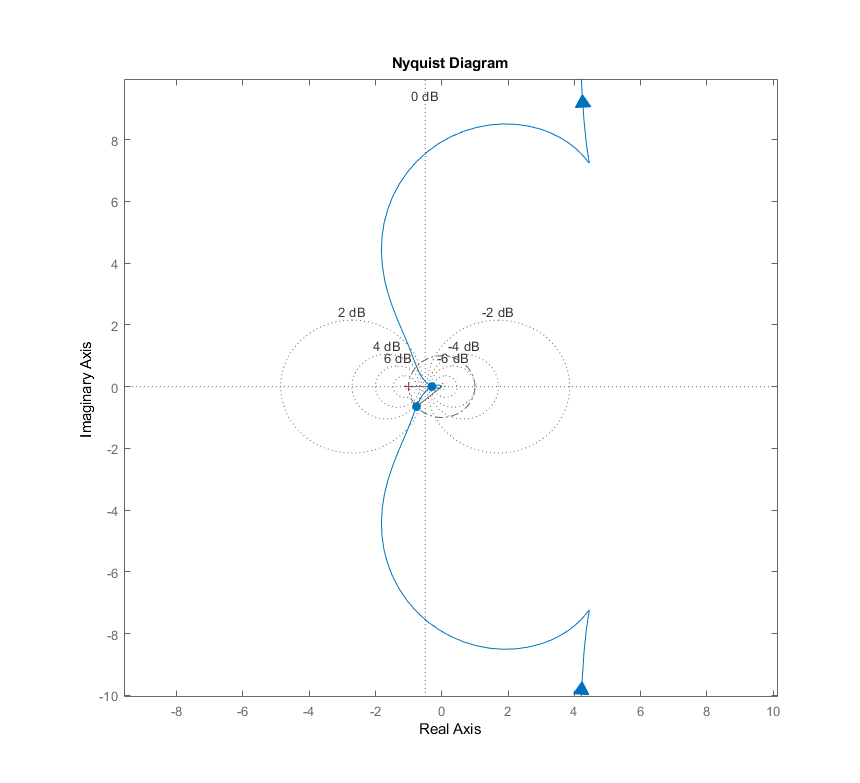

by considering the max frequency as 50$rad/s$, we get Nyquist plot as below for the designed system-

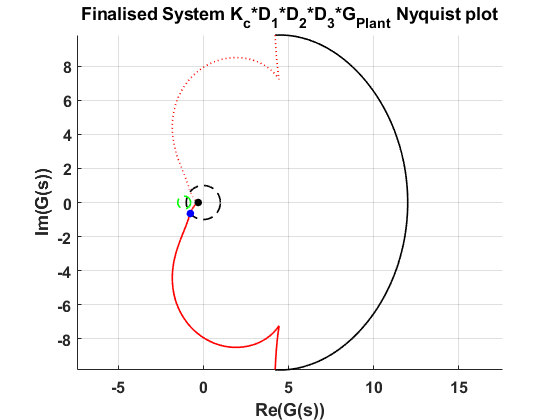

g = g1*D1*D2*D3*10;
r = 1.5;                        % Define radius for the pole at the origin
wMax = 50;                      % largest w value

%% s = rj -> wMax j
s1 = (r:.1:wMax)' * (1i);       % getting s value on imaginary axis to substitute in transfer function for obtaining nyquit plot points
nyq1 = zeros(size(s1));
for k = 1:length(s1)
    nyq1(k) = evalfr(g,s1(k));  % Getting nyquist plot points
end

%% s = re^(j*phi), phi = -90 -> 90
phi = (-90:1:90)';              % getting phi for values at circle considered in nyquist plot 
s2 = ( r*cosd(phi) + (1i)*r*sind(phi) ); % value of comples number to substitute in transfer function for getting nyquist plot values
nyq2 = zeros(size(s2));
for k = 1:length(s2)
    nyq2(k) = evalfr(g,s2(k));  % evaluation nyquist plot values
end

%% s = -rj -> -wMax j
s1a = (-r:-.01:-wMax)' * (1i);  % for -ve side of the imaginary axis
nyq1a = zeros(size(s1a));       
for k = 1:length(s1a)
  nyq1a(k) = evalfr(g,s1a(k));  % evaluating points for the nyquist plot
end

%% Unit Circle- for phase margin
tht = 0:1:359;
x = cosd(tht);          % x points on the unit circle
y = sind(tht);          % y points on the unit circle

%% An M circle- for resonant frequncy, bandwidth
M = -3;
tht=0:1:359;
r = abs(M./(M.^2-1));   % radius for m circle
xc = M.^2./(1-M.^2);    % x related point on the M circle
for k=1:length(xc)
  mc(k).c = xc(k) + r(k)*(cosd(tht)+sind(tht)*(1i));    % points for the M circle with respect to M value
end

%% PM- with help from unit circle cross point in the nyquist plot
idL = find(abs(nyq1)<1,1);      % find number of values on nyquist data less than magnitude of 1 for complex number
idH = idL-1;                    % subtract 1 from the total number values
ww = [s1(idL) s1(idH)];         % new vector with two points having magnitude on either side of magnitude 1
                                % abs(s1(idL))<1<abs(s1(idH))
mm = abs([nyq1(idL) nyq1(idH)]);% new vector with values of those magnitude
wGC = interp1(mm,ww,1);         % interpolation command to otain exact s value which lies on unity circle
pPT = evalfr(g,wGC);            % determining the complex number lying on unity circle and on nyquist plot
zAng = angle(pPT)*180/pi - 180; % phase margin for the point obtained
% to represent the phase margin with -180 to 180 window as displayed with margin command 
if zAng < -180
  pM = (zAng+360);
else
  pM = (zAng);
end

%% GM
idL = find(imag(nyq1)>0,1); % finding no of values in nyquist which are on +ve side of imaginary axis(or I and II quadrant) 
wPC = s1(idL);              % finding first number at which crossover happened
gM = -20*log10(abs(nyq1(idL))); % calulating dB value for the cross over point
gPT = nyq1(idL);                % storing point for further use in graph

%% Plotting of figure
id5 = id4+1;
h(id5).fig = figure(id5);
h(id5).axs = axes;
h(id5).ln(1) = line(real(nyq1),imag(nyq1),'Color','r','LineStyle','-','Linewidth',LW);  % plot corresponding to points on imaginary axis after small circle for the pole at origin
h(id5).ln(2) = line(real(nyq2),imag(nyq2),'Color','k','LineStyle','-','Linewidth',LW);  % plot corresponding to small circle around point at origin
h(id5).ln(3) = line(real(nyq1a),imag(nyq1a),'Color','r','LineStyle',':','Linewidth',LW);% plot corresponding to - ve side points on the imaginary axis    
h(id5).ln(4) = line(x,y,'Color','k','LineStyle','--','Linewidth',LW);                   % unit circle plot
% blue dot for phase margin
h(id5).ln(5) = line(real(pPT),imag(pPT),'Marker','o','MarkerSize',5,'LineStyle','none','Color','b','MarkerFaceColor','b');
% blue dot for gain margin
h(id5).ln(6) = line(real(gPT),imag(gPT),'Marker','o','MarkerSize',5,'LineStyle','none','Color','k','MarkerFaceColor','k');
% plot for M circles
for k=1:length(mc)
    h(id5).ln(6+k) = line(real(mc(k).c),imag(mc(k).c),'Color','g','LineStyle','--','Linewidth',LW);
end

axis equal
h(id5).tit = title('Finalised System K_{c}*D_{1}*D_{2}*D_{3}*G_{Plant} Nyquist plot');
h(id5).xlb = xlabel('Re(G(s))');
h(id5).ylb = ylabel('Im(G(s))');
% h(id5).leg = legend('Points for +ve Imag axis s-value','Points corre. to max frequency','Points for -ve Imag axis s-value','Unit Circle','PM','GM','3dB circle');
h(id5).axs.FontSize   = FS;                   % axis font size for first plot
h(id5).axs.FontWeight = 'Bold';               % Set axis type for first plot
grid on

From the Nyquist plot available above, phase margin for the system observed to be 40.38deg as obtained by the final bode plot details and gain margin for the system observed to be 10.49dB. From figure it can be observed that further with loop gain for the system can be used, of value for multiplication around 3 to designed system, beyond which it will go unstable.

## Simulations for the designed system

With finalized gain values and lead compensator designed as per the design requirement, assumption made for system to have simulation error of less than 1%, calculated integration step size for simulation by below formula-


$$e_{\lambda} = -e_I({\lambda}T)^k$$


where,$e_{\lambda} = $ max allowable error possible

$e_I = $values corresponding to Integration method

$\lambda =$ max eigen value for the system

$k=$ order of integration

%% Time step calculations for RK-4
%Getting Eigen values for integration step size for RK-4
cls01ei = roots(gcl.Denominator{1});
% Calculations to find time step for first simulations
lambda_max_sc = max(abs(cls01ei));      % Maximum eigen value to be used for 
                                        % time step calculations
e_lambda = 0.01;                        % Maximum error of 1% in simulations

% Considering RK-4 method for integration we have e_I = 1/120 and k = 4
e_I = 1/120;
k = 4;
Tstep2 = (e_lambda/e_I)^(1/k)/(lambda_max_sc);

Integration method used is RK-4, which required integration step size $T$ less than 0.0144sec, for error in simulation less than 1%. Hence, selecting integration step size as 0.0072 which is around 1/2 of the 0.0144 required for error less than 1%.

Below are the simulation model used for Simulation with step response details-

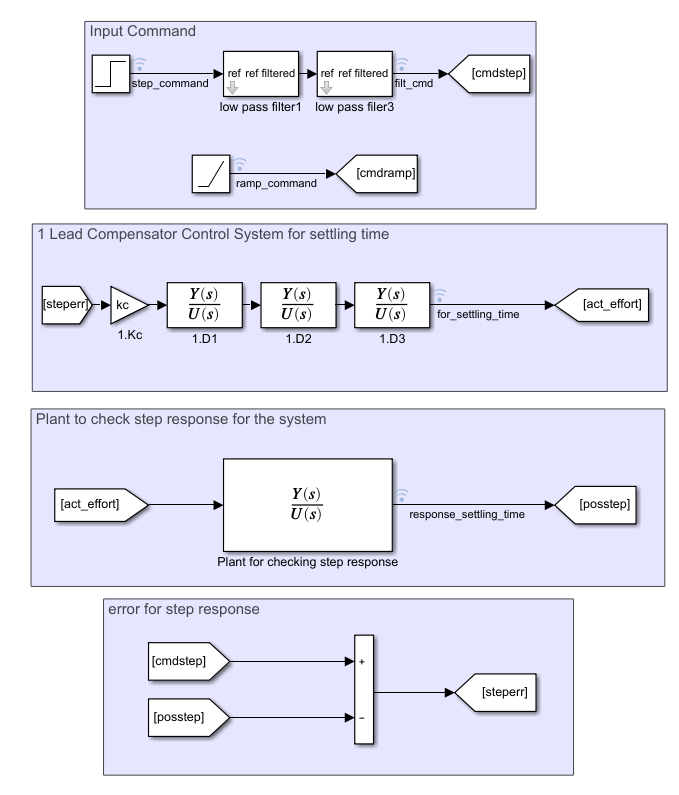

Results obtained from the simulation are as below-

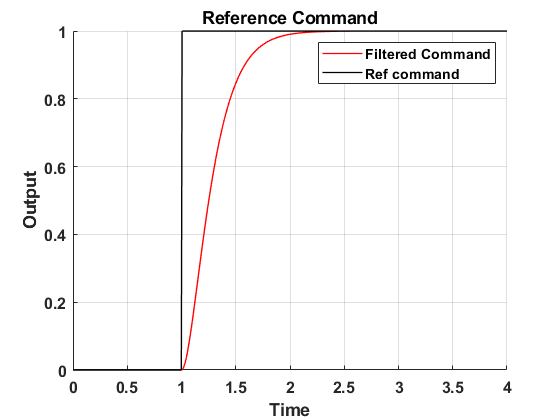

% Getting data for the step input command details to the system
% Step Command Details
a.T0 = 1;                   % Step Start time
a.A = 1;                    % Amplitude of the step
b.A = 1;                    % Slope for the ramp
b.T0 = 0;                   % Amplitude of the disturbance

%% Values for the system
tdrb = 0.025;               % Time delay for system to go away from requirement
tdu = 0.0324;               % Time delay for system to go unstable

%% Setting up the model parameters required
mName = 'p3Sim';            % Name for the final model for sensor dynamics 
                            % and disturbance details
open_system(mName)          % Opening the model
Simulink.sdi.clear          % Clearing initial data in simulink

%% Running Simulations
s.TFinal = 10;                           % time for running simulatons in sec
s.Tstep = Tstep2/2;                             % AS designed for error less than
                                                % 1% in the simulink model
                                                % with Euler integration as
                                                % type for integration
sOut = sim('p3Sim','SignalLoggingName','sdat'); % Executing simulations

% Getting Data from Simulink Model and plotting the result
% Defining indices from the Simulink
se_act = 1;                                     % actuator effort for settling time 
ess_act = 2;                                    % actuator effort for staedy state error
ess_res = 3;                                    % response for steady state error
se_res = 4;                                     % Output for settling time
td_set = 5;                                     % timedelay response for settling time
td_unst = 6;                                    % time delay response for unstable syste
ra_ref = 7;                                     % ramp reference input
se_ref = 8;                                     % step reference input
ess = 9;                                        % Steady state error
se_fil = 10;                                    % step filtered input

%Plot Parameters
LW=1;                                               %linewidth
FS= 12;                                             %Fontsize
FILETYPE= '-depsc';                                 %graphic file type
FNAME1 = 'Reference Command';                       %filename for input details 

%Grab data fro plotting from simulink
t = sOut.sdat{se_ref}.Values.Time;             % Time details for simulations
rstep =sOut.sdat{se_ref}.Values.Data;          % step reference command
fstep =sOut.sdat{se_fil}.Values.Data;          % filtered step reference command
restep = sOut.sdat{se_res}.Values.Data;        % Output from step command
actstep = sOut.sdat{se_act}.Values.Data;       % Actuator response for the step input
rampref = sOut.sdat{ra_ref}.Values.Data;       % Ramp reference command
ramout = sOut.sdat{ess_res}.Values.Data;       % Ramp output details command
err = sOut.sdat{ess}.Values.Data;              % Steady state error for the system
 
% Step reference input for settling time
id6 = id5+1;
h(id6).fig =figure(id6);                      % makeing figure
h(id6).axs =axes;                             % Make axies
h(id6).ln(1)=line(t,fstep,'Color','r');       % Flitered command to system
h(id6).ln(2)=line(t,rstep,'Color','k');       % Original Input command
h(id6).xlb = xlabel('Time');                  % Xlabel for plot1
h(id6).ylb = ylabel('Output');                % Ylabel for plot1
h(id6).leg = legend('Filtered Command','Ref command'); % legends
% ylim([0 1.5])                                 % Limits for y axis for proper representation
xlim([0 4])                                 % X limits for representation
h(id6).tit = title(FNAME1);                   % title for plot
%Plot formatting
for i=1:length(h(id6).ln)                     % Setting linewidth for first plot
    h(id6).ln(i).LineWidth = LW;
end
h(id6).axs.FontSize   = FS;                   % axis font size for first plot
h(id6).axs.FontWeight = 'Bold';               % Set axis type for first plot
grid;

Above figure provide the details of the reference command provided to the system. Black line represents the original step command provided and red line represent the command going to the system after band limited filters used.

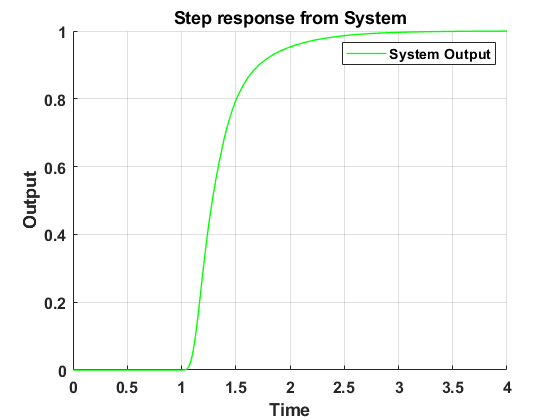

% Step reference output for settling time
FNAME2 = 'Step response from System';                       %filename for input details 
id7 = id6+1;
h(id7).fig =figure(id7);                      % makeing figure
h(id7).axs =axes;                             % Make axies
h(id7).ln(1)=line(t,restep,'Color','g');      % Output recieved from the system
h(id7).xlb = xlabel('Time');                  % Xlabel for plot1
h(id7).ylb = ylabel('Output');                % Ylabel for plot1
h(id7).leg = legend('System Output');         % legends
% ylim([0.94 1])                                 % Limits for y axis for proper representation
xlim([0 4])                                 % X limits for representation
h(id7).tit = title(FNAME2);                   % title for plot
%Plot formatting
for i=1:length(h(id7).ln)                     % Setting linewidth for first plot
    h(id7).ln(i).LineWidth = LW;
end
h(id7).axs.FontSize   = FS;                   % axis font size for first plot
h(id7).axs.FontWeight = 'Bold';               % Set axis type for first plot
grid;

S2.SettlingTime

ans = 0.9765

Figure provide the details for the step response output from the system. From the figure settling time for 5% settling observed to be 0.95sec against required of 1sec. Below are the zoomed response details showing system going above 0.95 of original value at around 1.95 sec agianst the step starting at 1 sec.

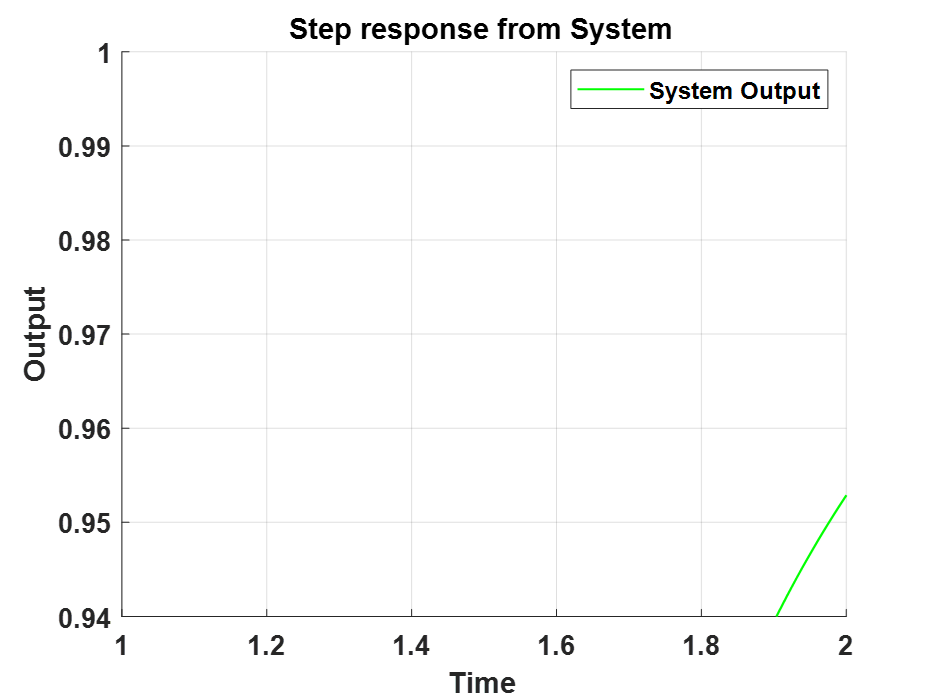

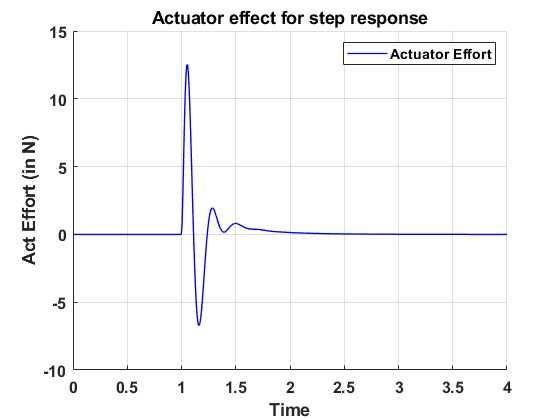

% Step reference actuator effort
FNAME3 = 'Actuator effect for step response'; %filename for input details 
id8 = id7+1;
h(id8).fig =figure(id8);                      % makeing figure
h(id8).axs =axes;                             % Make axies
h(id8).ln(1)=line(t,actstep,'Color','b');     % Output recieved from the system
h(id8).xlb = xlabel('Time');                  % Xlabel for plot1
h(id8).ylb = ylabel('Act Effort (in N)');     % Ylabel for plot1
h(id8).leg = legend('Actuator Effort');       % legends
% ylim([0.94 1])                              % Limits for y axis for proper representation
xlim([0 4])                                   % X limits for representation
h(id8).tit = title(FNAME3);                   % title for plot
%Plot formatting
for i=1:length(h(id8).ln)                     % Setting linewidth for first plot
    h(id8).ln(i).LineWidth = LW;
end
h(id8).axs.FontSize   = FS;                   % axis font size for first plot
h(id8).axs.FontWeight = 'Bold';               % Set axis type for first plot
grid;

Figure above provide the details for the actuator effort, with filters in the system actuator effort observed to be less than +$15N$. And at around 2 seconds actuator effort are going to zero as system is getting settled.

Below is the model used for ramp command response for verifying steady state error of the system-

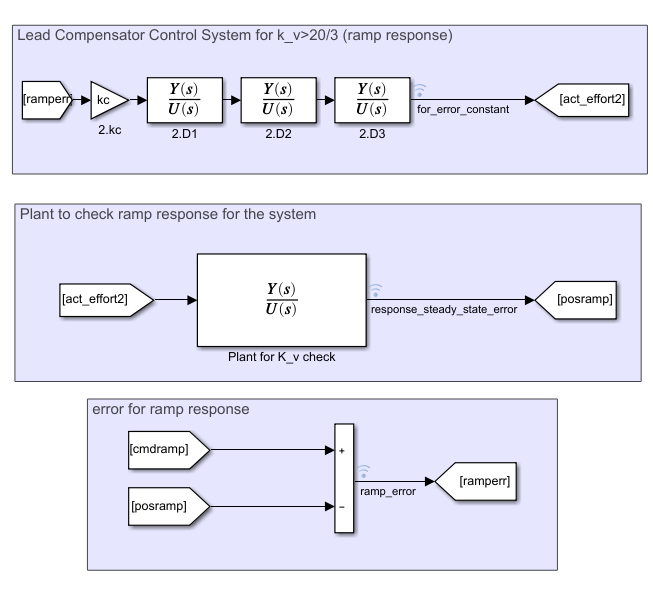

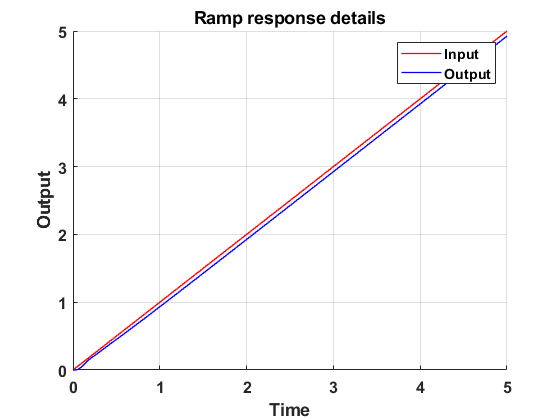

% Ramp input and output for the steady state error
FNAME4 = 'Ramp response details'; %filename for input details 
id9 = id8+1;
h(id9).fig =figure(id9);                      % makeing figure
h(id9).axs =axes;                             % Make axies
h(id9).ln(1)=line(t,rampref,'Color','r');     % Flitered command to system
h(id9).ln(2)=line(t,ramout,'Color','b');      % Original Input command
h(id9).xlb = xlabel('Time');                  % Xlabel for plot1
h(id9).ylb = ylabel('Output');                % Ylabel for plot1
h(id9).leg = legend('Input','Output');        % legends
% ylim([0 1.5])                               % Limits for y axis for proper representation
xlim([0 5])                                   % X limits for representation
h(id9).tit = title(FNAME4);                   % title for plot
%Plot formatting
for i=1:length(h(id9).ln)                     % Setting linewidth for first plot
    h(id9).ln(i).LineWidth = LW;
end
h(id9).axs.FontSize   = FS;                   % axis font size for first plot
h(id9).axs.FontWeight = 'Bold';               % Set axis type for first plot
grid;

Figure above provide the details for the system response for the ramp input, verified for the steady state error less than $\frac{3}{20}$ or $K_v>\frac{20}{3}$

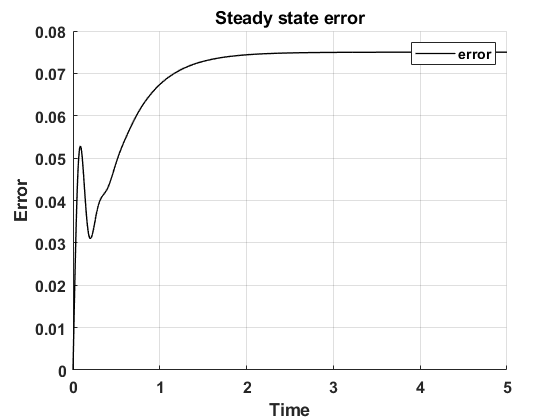

% Steady state error details
FNAME5 = 'Steady state error'; %filename for input details 
id10 = id9+1;
h(id10).fig =figure(id10);                      % makeing figure
h(id10).axs =axes;                              % Make axies
h(id10).ln(1)=line(t,err,'Color','k');          % Flitered command to system
h(id10).xlb = xlabel('Time');                   % Xlabel for plot
h(id10).ylb = ylabel('Error');                  % Ylabel for plot
h(id10).leg = legend('error');                  % legends
% ylim([0 1.5])                                 % Limits for y axis for proper representation
xlim([0 5])                                     % X limits for representation
h(id10).tit = title(FNAME5);                    % title for plot
%Plot formatting
for i=1:length(h(id10).ln)                      % Setting linewidth for first plot
    h(id10).ln(i).LineWidth = LW;
end
h(id10).axs.FontSize   = FS;                   % axis font size for first plot
h(id10).axs.FontWeight = 'Bold';               % Set axis type for first plot
grid;

Above graph provide the details for the error observed in the system for the ramp input. Steady state error for the system observed to be 0.075.

We have, $ess = \frac{A}{K_v}$, where $A = 1$

% verifying steady state error
kv = 1/0.075;

Hence, we get, $K_v = 13.33>\frac{20}{3}$

With the simulations system designed observed to be within design requirements for the system.

## Effect of Time Delay $T_d$ on System - Going away from the design 

With time delay in feedback, system response starts to vary and even though closed loop system is stable, due to time delay it can go unstable.

Initial design for the system was done for $PM>40$ and settling time for 5% settling less than 1 sec.

With the help of the system designed and using the MATLAB code provide below, time delay for system for $PM<40$ observed to be 0.4ms and for closed loop system to have settling time below 1sec for 5% settling observed to be 25ms.

System with time delay in the system can be represented with below block diagram-

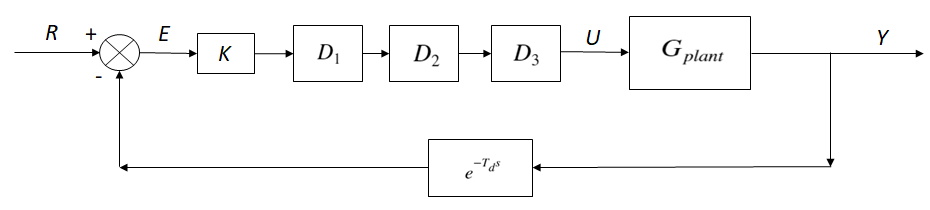

Plant equation to consider time delay in the system can be modified to as shown below-

For system having 5% settling time more than 1 sec equation can be written as-


$$G_{plant} = e^{-0.025s} \frac{50(s+4)}{s(s+6)(s^2+4s+25)}$$


For system to have PM<40, plant equation with time delay can be written as,


$$G_{plant} = e^{-0.0004s} \frac{50(s+4)}{s(s+6)(s^2+4s+25)}$$


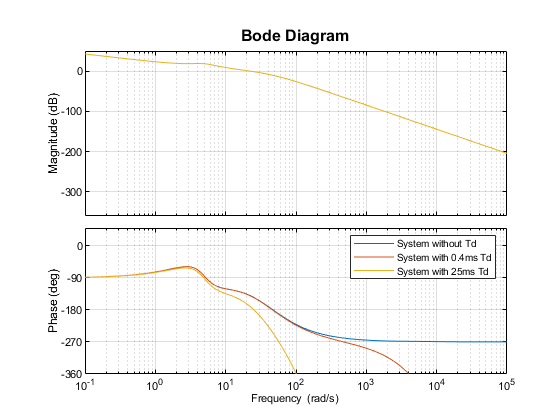

% Time delay in system for detoriating from the requirement provided
% td = 0.0001:0.0001:1;
% for ii=1:length(td)
%     gtd = tf(50*[1 4],conv([1 6 0],[1 4 25]),'InputDelay',td(ii));
%     gcl = feedback(kc*D1*D2*D3*gtd,1);
%     S3 = stepinfo(tf_filt*tf_filt*gcl,'SettlingTimeThreashhold',ST);
%     if S3.SettlingTime>=1
%         tdrb1 = td(ii)
%         break
%     end
% end
% for ii=1:length(td)
%     gtd = tf(50*[1 4],conv([1 6 0],[1 4 25]),'InputDelay',td(ii));
%     [m34,p34] = margin(kc*D1*D2*D3*gtd);
%     if p34<40
%         tdrb2 = td(ii)
%         break
%     end
% end
tdrb = 0.024;
tdrbp = 4e-4;
% System transfer function with time delay
gtd1 = tf(50*[1 4],conv([1 6 0],[1 4 25]),'InputDelay',tdrb);
gtdp = tf(50*[1 4],conv([1 6 0],[1 4 25]),'InputDelay',tdrbp);
% Bode plot comparison for the system with time delay
% Defining parameters for uniform bode plot
b1 = bodeoptions;
b1.grid = 'on';
b1.Title.FontSize = 12;
b1.Title.FontWeight = 'bold';
b1.YLim =  [-360 50];
bode(kc*D1*D2*D3*g1,kc*D1*D2*D3*gtdp,kc*D1*D2*D3*gtd1,b1)
legend('System without Td','System with 0.4ms Td','System with 25ms Td');hold off

[mgtd,phtd] = margin(kc*D1*D2*D3*gtdp);

Above is the bode plot for the loop transfer function with time delay taken into consideration. As from the above graph for time delay of 0.4ms system observed to have phase margin of 39.8766deg against required of 40deg.

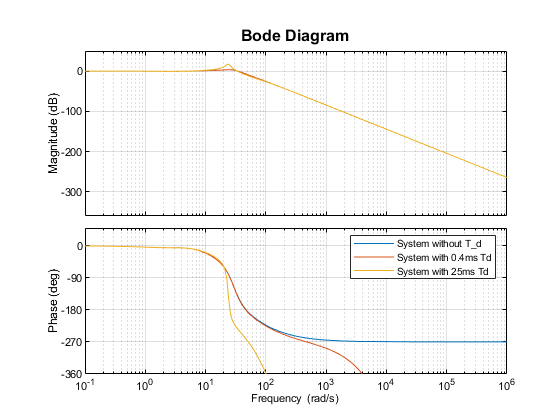

% closed loop transfer function for the time delay
gctd1 = feedback(kc*D1*D2*D3*gtd1,1);
gctdp = feedback(kc*D1*D2*D3*gtdp,1);

% bode plot for the closed loop system with time delay
b.YLim = [-720 50];
bode(gcl,gctdp,gctd1,b1)
legend('System without {T_d}','System with 0.4ms Td','System with 25ms Td');hold off

Above is the feedback from the system for with and without time delay, with addition of time delay there observed to be no change in the system for magnitude plot, but phase plot observed to have loss of phase with rise in the time delay. At time delay of 25ms, phase margin for the system observed to be of value around 9.5deg.

For checking settling time variation in the system time delay used was 25ms, and below simulation model used for the same.

 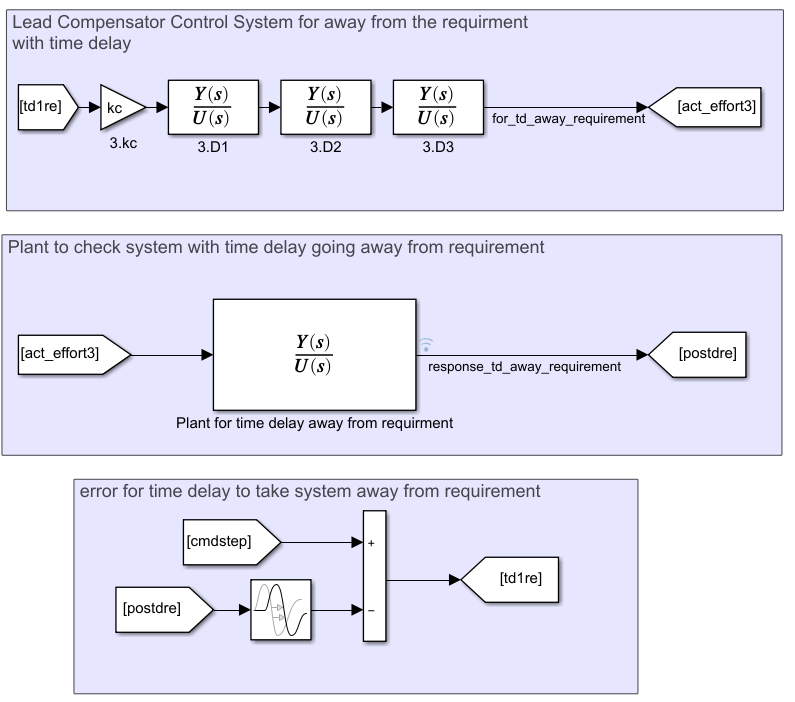

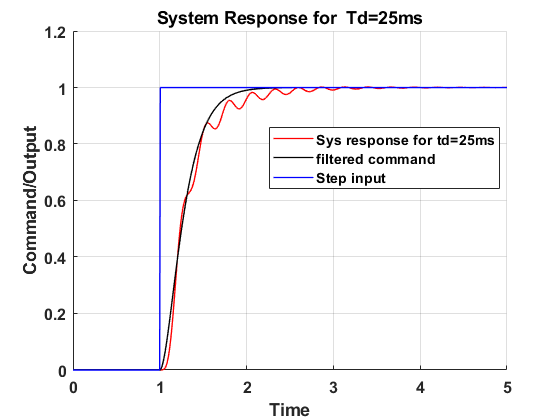

% Grabbing data from system for simulations
tdset = sOut.sdat{td_set}.Values.Data;              % Steady state error for the system

% Settling time variation details
FNAME6 = 'System Response for  Td=25ms';        %filename for input details 
id11 = id10+1;
h(id11).fig =figure(id11);                      % makeing figure
h(id11).axs =axes;                              % Make axies
h(id11).ln(1)=line(t,tdset,'Color','r');        % time delayed output from system
h(id11).ln(2)=line(t,fstep,'Color','k');        % Flitered command to system
h(id11).ln(3)=line(t,rstep,'Color','b');        % Original Input command
h(id11).xlb = xlabel('Time');                   % Xlabel for plot
h(id11).ylb = ylabel('Command/Output');         % Ylabel for plot
h(id11).leg = legend('Sys response for td=25ms','filtered command','Step input','Location','best');% legends
% ylim([0.9 1.2])                                 % Limits for y axis for proper representation
xlim([0 5])                                     % X limits for representation
h(id11).tit = title(FNAME6);                    % title for plot
%Plot formatting
for i=1:length(h(id11).ln)                      % Setting linewidth for first plot
    h(id11).ln(i).LineWidth = LW;
end
h(id11).axs.FontSize   = FS;                   % axis font size for first plot
h(id11).axs.FontWeight = 'Bold';               % Set axis type for first plot
grid;

Figure above provide the details for the system with variation from required settling time for 5% settling going away from the required 1sec. Figure below provide the details of the variations observed with time delay of 25ms. 

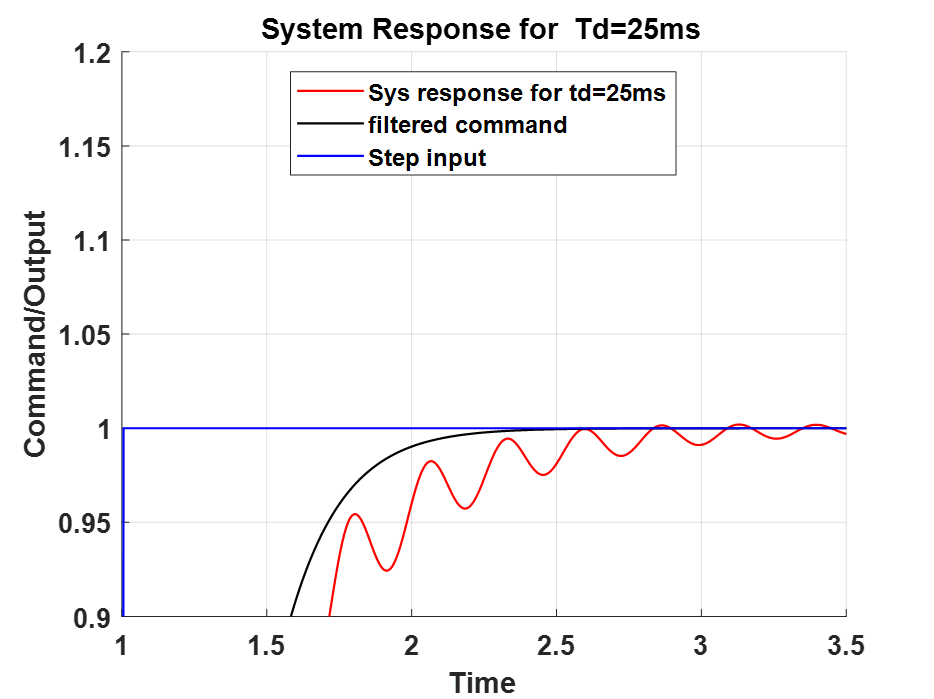

From the above graphs and discussion available, it can be concluded that for maintaining the $PM>40$ fast sensor is required, as time delay allowed in this case is 0.4ms. For maintaining 5% settling less than 1sec, slightly slow sensor in comparison with the one required for $PM>40$ can be utilized as system observed to cross that requirement at time delay of 25ms as compared to earlier one of 0.4ms. 

## Effect of Time Delay $T_d$ - System going unstable

From the MATLAB code provided below, time delay for system to go unstable observed to be 32.4ms.

Plant equation with this time delay identified can be written as below-


$$G_{plant} = e^{-0.0324s} \frac{50(s+4)}{s(s+6)(s^2+4s+25)}$$


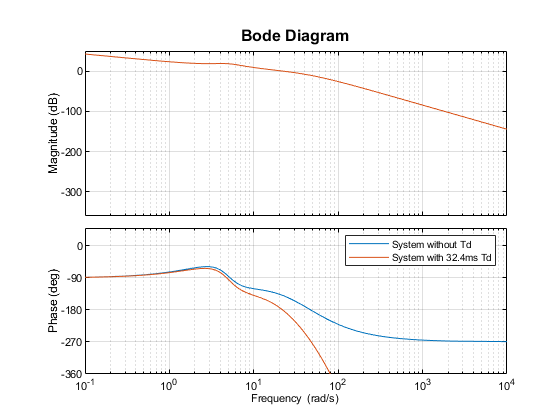

%% Time delay for system to go unstable
% td = tdrb:0.001:1.5;
% for ii = 1:length(td)
%     gtd = tf(50*[1 4],conv([1 6 0],[1 4 25]),'InputDelay',td(ii));
%     [m34,p34] = margin(kc*D1*D2*D3*gtd);
%     if p34<=0.05
%         tdu = td(ii)
%         break
%     end
% end
tdu = 0.0324;
% System transfer function with time delay
gtd2 = tf(50*[1 4],conv([1 6 0],[1 4 25]),'InputDelay',tdu);
% bode plot for the open loop system in comparison with variation from
% without time delay
b1.YLim =  [-360 50];
bode(kc*D1*D2*D3*g1,kc*D1*D2*D3*gtd2,b1)
legend('System without Td','System with 32.4ms Td');hold off

[mtun,phun] = margin(kc*D1*D2*D3*gtd2);

Figure above provide the details of the Bode plot comparison of the system for loop transfer function, as observed earlier in magnitude plot no change observed in the system. But in phase plot, system starts to lose phase with increase in time delay. At time delay of 32.4ms, system have phase margin of -0.81deg, and the system goes unstable.

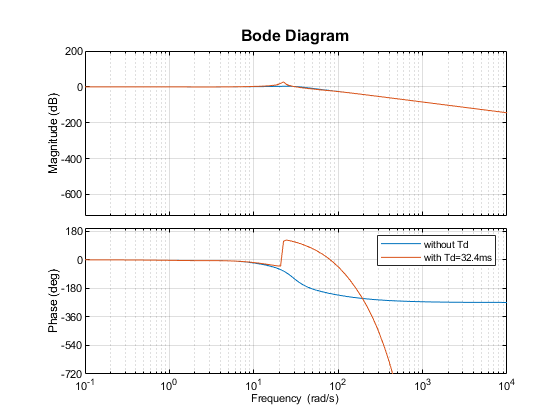

% closed loop transfer function for the time delay
gctd2 = feedback(kc*D1*D2*D3*gtd2,1);
% bode plot for comparison
b1.YLim = [-720 200];
bode(gcl,gctd2,b1)
legend ('without Td','with Td=32.4ms')

Figure above provide the details of the closed loop bode plot for the time delayed system. As seen from the graph above system observed to lose phase rapidly at time delay of 32.4ms and goes unstable.

Below is the Simulink model used for the simulation for the system going unstable with time delay-

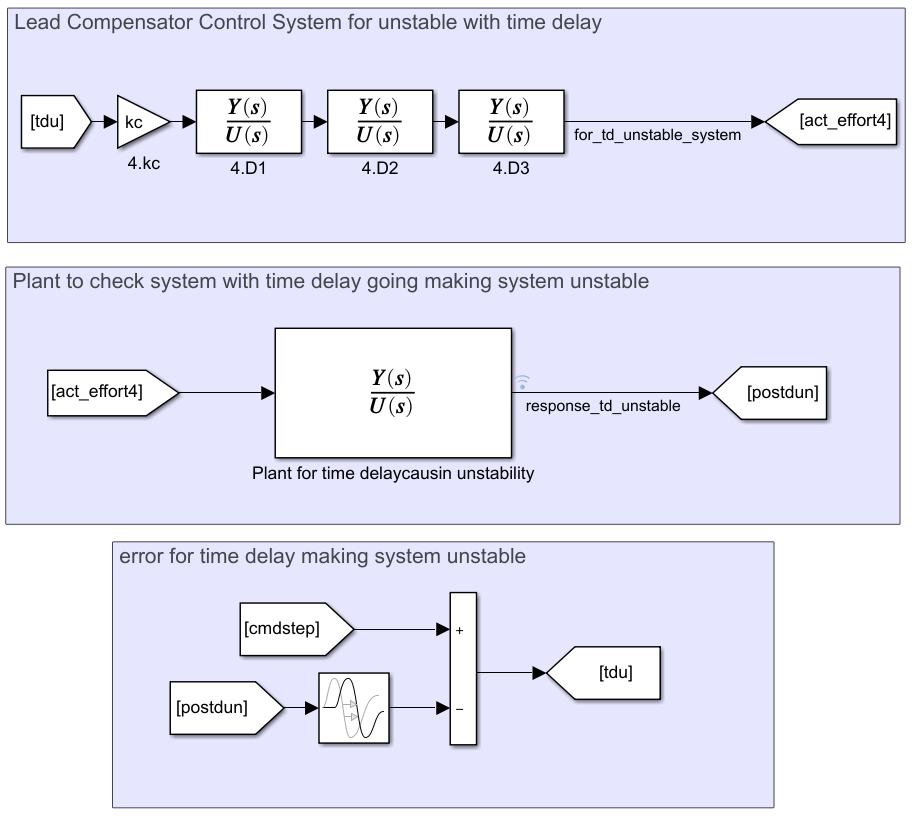

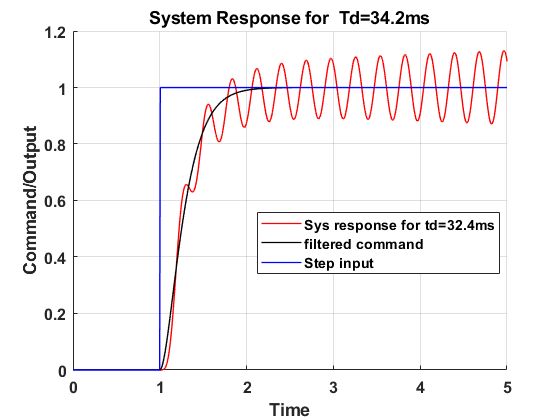

% Grabbing data from system for simulations
tduns = sOut.sdat{td_unst}.Values.Data;         % Steady state error for the system

% Settling time variation details
FNAME7 = 'System Response for  Td=34.2ms';      %filename for input details 
id12 = id11+1;
h(id12).fig =figure(id12);                      % makeing figure
h(id12).axs =axes;                              % Make axies
h(id12).ln(1)=line(t,tduns,'Color','r');        % time delayed output from system
h(id12).ln(2)=line(t,fstep,'Color','k');        % Flitered command to system
h(id12).ln(3)=line(t,rstep,'Color','b');        % Original Input command
h(id12).xlb = xlabel('Time');                   % Xlabel for plot
h(id12).ylb = ylabel('Command/Output');         % Ylabel for plot
h(id12).leg = legend('Sys response for td=32.4ms','filtered command','Step input','Location','best');% legends
% ylim([0.9 1.2])                                 % Limits for y axis for proper representation
xlim([0 5])                                     % X limits for representation
h(id12).tit = title(FNAME7);                    % title for plot
%Plot formatting
for i=1:length(h(id12).ln)                      % Setting linewidth for first plot
    h(id12).ln(i).LineWidth = LW;
end
h(id12).axs.FontSize   = FS;                   % axis font size for first plot
h(id12).axs.FontWeight = 'Bold';               % Set axis type for first plot
grid;

Above figure provide the details of the system response for the time delay of 32.4ms. At$T_d=32.4ms$ system starts to go unstable. From the above graphs, if the feedback from the system requires more time than 32.4ms to flow back to compensator, though designed properly system will go unstable.  

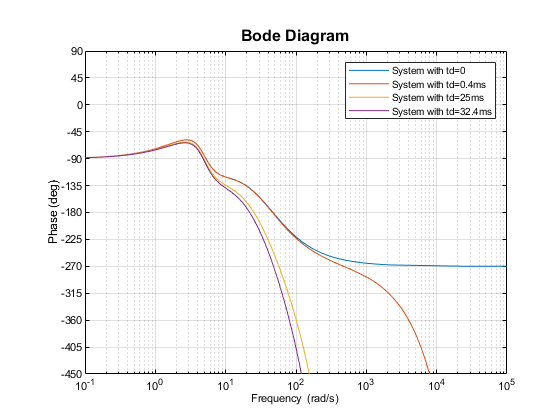

% bode plot for comparison of open loop system
b2 = bodeoptions;
b2.grid = 'on';
b2.MagVisible = 'off';
b2.Title.FontSize = 12;
b2.Title.FontWeight = 'bold';
b2.YLim = [-450 90];
bode(kc*D1*D2*D3*g1,kc*D1*D2*D3*gtdp,kc*D1*D2*D3*gtd1,kc*D1*D2*D3*gtd2,b2)
legend('System with td=0','System with td=0.4ms','System with td=25ms','System with td=32.4ms')

Above is the phase plot of the bode plot for the all the systems, discussed above. From the graph with rise in time delay, system starts to lose the phase and moves towards becoming unstable.

## Summary

 For provided system, gain required to satisfy the system's velocity error constant requirement observed to make system unstable and taking phase margin in -ve. To make the system stable with the gain finalized lead compensators were designed to obtain the $PM>40$. While designing phase lead compensators design was done for the additional phase than required as with steep loss in phase in the unstable region, final phase margin obtained after adding the phase lead compensator is less than targeted. 

Hence, to obtain the phase margin of 40degree 3 lead compensators were designed two of which are having phase of 49 deg and one having phase of 23deg, to obtain the total PM of 40.8, from the observed -42.5 with gain required for the system.

From the designed system, actuator requirement was not confirmed, hence simulations were required to check for meeting actuator requirement. With initial designed system and having gain in the system due to sudden rise in the command, large actuator force was required to satisfy the other design requirements, hence filters were introduced to smooth out the input command to reduce actuator effort. With addition of filters settling time for the system observed to be changed, whereas no effect of the same observed for steady state error and phase margin of the system. Hence to satisfy the requirement for settling time, system redesigned with higher gains and less settling time.

With introduction of time delay in system, system observed to lose phase rapidly with rise in time delay to the signal received. It was evident from the phase plot of the bode plot, whereas there observed nearly no change in magnitude plot. 

It was observed that designed phase margin acts as a cushion to avoid system for going unstable or delay in response to the settling time designed. It was evident from the fact that time delay required to overcome the settling time requirement was 25ms as compared to the time delay required to overcome the $PM$ requirement which was 0.4ms. 

With time delay introduced in the system, it was observed that though designed system is stable with good phase margin, system went unstable with higher time delay of around 32.4sec.

Time delay factor evidently provide the implications of the sensors used, with the slow sensors time required to receive the feedback increases, thus increasing the time delay, due to which well-designed system can also go unstable.

## Conclusion

System designed with numerical calculations, required to be verified with simulations to check for the actuator efforts which provide the idea for problems might be faced due to limitations of the actuator. It provided the way out to redesign the system, to avoid any new surprises at last minute.

Once designed, system should be verified for the time delay component. As with various system in use, there will always be some delay in receiving the feedback depending on the sensor it might be of few milliseconds to seconds. It also depends upon time constant of the sensor, Dc gain of the sensor, condition of the sensor, detoriation in sensor quality over the use period, environment in which sensor is to be used etc. Verifying system against the time delay component provide way to counteract some of the issues which might be faced in real world, it also provides means to select the sensors which can be used for the desired operation.


$$$$


## MATLAB Code Used